Generate Sample data and save as csv 

tx = linspace(0, 1, 8); 

x = cos(tx); 

T = table(tx', x', 'VariableNames', {'Time', 'x'}); 

writetable(T, 'dx.csv', 'Delimiter', ','); 

disp(T) 

     Time         x   
    _______    _______

          0          1
    0.14286    0.98981
    0.28571    0.95946
    0.42857    0.90956
    0.57143    0.84113
    0.71429    0.75556
    0.85714     0.6546
          1     0.5403



load data from local file, online source 

% local source  

T1 = readtable('dx.csv'); 

% online source  

T2 = readtable('http://apmonitor.com/pds/uploads/Main/dx.txt'); 

Load data with more control 

% Open the file  

fid = fopen('dx.csv', 'r'); 

% Read and display each line  

while ~feof(fid) line = fgetl(fid); disp(line) 
end

Time,x
0,1
0.142857142857143,0.989813260446615
0.285714285714286,0.959460581111917
0.428571428571429,0.909560351674167
0.571428571428571,0.841129213415236
0.714285714285714,0.755561346700697
0.857142857142857,0.654600066675268
1,0.54030230586814



% Close the file  

fclose(fid); 

 

% Open the file  

fid = fopen('dx.csv', 'r'); 

% Read the first 4 characters  

x = fread(fid, 4, 'char=>char'); disp(x) 

T
i
m
e



% Close the file  

fclose(fid); 

 

% Open the file  

fid = fopen('dx.csv', 'r'); 

% Read and display the first line  

line = fgetl(fid); disp(line) 

Time,x



% Read and display the second line  

line = fgetl(fid); disp(line) 

0,1



% Read and display the third line  

line = fgetl(fid); disp(line) 

0.142857142857143,0.989813260446615



% Close the file  

fclose(fid); 

join data,

tx = linspace(0,1,4); 
tx=tx.'

tx =          0
    0.3333
    0.6667
    1.0000


x = cos(tx); 
dx = table(tx,x,'VariableNames',{'Time','x'}); 

ty = linspace(0,1,3); 
ty=ty.'

ty =          0
    0.5000
    1.0000


y = sin(ty); 
dy = table(ty,y,'VariableNames',{'Time','y'}); 

     Time         x   
    _______    _______

          0          1
    0.33333    0.94496
    0.66667    0.78589
          1     0.5403



    Time       y   
    ____    _______

      0           0
    0.5     0.47943
      1     0.84147




z= innerjoin(dx,dy, "LeftKeys","Time","RightKeys","Time")

z = 2×3 table
    Time      x          y   
    ____    ______    _______

     0           1          0
     1      0.5403    0.84147


z= outerjoin(dx,dy,"Type","left","RightVariables","y")

z = 4×3 table
     Time         x          y   
    _______    _______    _______

          0          1          0
    0.33333    0.94496        NaN
    0.66667    0.78589        NaN
          1     0.5403    0.84147


z= outerjoin(dy,dx,"Type","left","RightVariables","x")

z = 3×3 table
    Time       y         x   
    ____    _______    ______

      0           0         1
    0.5     0.47943       NaN
      1     0.84147    0.5403


z= outerjoin(dx,dy, "Keys","Time","MergeKeys",true)

z = 5×3 table
     Time         x          y   
    _______    _______    _______

          0          1          0
    0.33333    0.94496        NaN
        0.5        NaN    0.47943
    0.66667    0.78589        NaN
          1     0.5403    0.84147


Append data 

tx = linspace(0,1,4); 

x = cos(tx); 

dx = table(tx',x','VariableNames',{'Time','x'}); 

tx = linspace(0,1,3); 

x = cos(tx); 

dy = table(tx',x','VariableNames',{'Time','x'}); 

Full= vertcat(dx,dy); 

result = sortrows(Full,'Time'); 

result = unique(result,'rows','stable'); 

result(:,:) = result; 

result 

result = 5×2 table
     Time         x   
    _______    _______

          0          1
    0.33333    0.94496
        0.5    0.87758
    0.66667    0.78589
          1     0.5403


Activity 

% stock ticker symbol   

url = 'http://apmonitor.com/pds/uploads/Main/goog.txt';  

% import data with readtable   

data = readtable(url,'VariableNamingRule','preserve'); 

disp(data); 

       Date        Open      High      Low      Close     Adj Close      Volume  
    __________    ______    ______    ______    ______    _________    __________

    2017-09-11    934.25    938.38    926.92    929.08     929.08       1.267e+06
    2017-09-12    932.59    933.48    923.86    932.07     932.07      1.1344e+06
    2017-09-13    930.66    937.25    929.86    935.09     935.09      1.1026e+06
    2017-09-14    931.25    932.77       924    925.11     925.11      1.3976e+06
    2017-09-15    924.66    926.49    916.36    920.29     920.29      2.5054e+06
    2017-09-18    920.01    922.08     910.6       915        915      1.3069e+06
    2017-09-19    917.42    922.42    912.55    921.81     921.81       9.367e+05
    2017-09-20    922.9

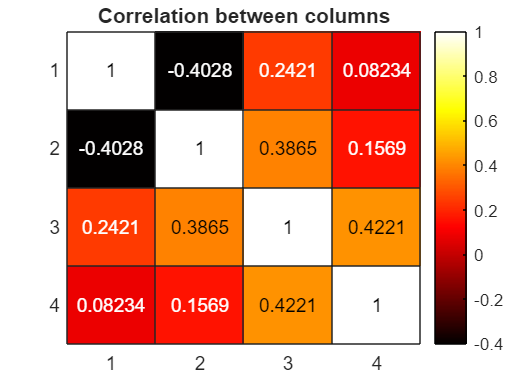


% calculate change and volatility   

data.Change = data.Close-data.Open;   

data.Volatility = data.High-data.Low;   

analysis = {'Open','Volume','Volatility','Change'};  

corr_data = corr(table2array(data(:,analysis))); 

% Plot heatmap 

heatmap(corr_data, 'Colormap', hot); 

colorbar; 

title('Correlation between columns'); 